# Homework 3: Self organising map

The files [iris-data.csv](https://nn-2022.opentaproject.com/exercise/28740b89-8256-4ce7-91d2-2f52f5179ef3/asset/iris-data.csv) and [iris-labels.csv](https://nn-2022.opentaproject.com/exercise/28740b89-8256-4ce7-91d2-2f52f5179ef3/asset/iris-labels.csv) contain input and targets from the Iris-flower data set (see Ref. [70] in the course book), with data from three species of Iris flowers. You can read more about the data set here: [link](https://archive.ics.uci.edu/ml/datasets/iris). Train a self-organising map (p. 185 in the course book) to cluster the different flower species in the Iris data set. To do this, use the learning rule Eq. (10.17)


$$\delta\mathbf{w}_i=\eta h(i,i_0)(\mathbf{x}-\mathbf{w}_i)$$


where the neighbourhood function $h(i,i_0)$ is defined as (Eq. 10.18)


$$h(i,i_0)=\exp\left(-\frac{1}{2\sigma^2}|\mathbf{r}_i-\mathbf{r}_{i_0}|^2\right)$$


where $\mathbf{r}_i$ is the position of neuron $i$ in the output array.

Initialize the weight array by sampling $W_{ij}$ from a uniform distribution in the interval [0,1]. Use a $40\times40$ output array -- since the input dimension is $n=4$, the weight array has dimensions (40,40,4). The learning rate $\eta$ and the width $ \sigma$ of the neighbourhood function depend on the iteration number:


$$\eta=\eta_0\exp\left(-d_\eta\times\text{epoch} \right)$$


and


$$\sigma=\sigma_0\exp\left(-d_\sigma \times \text{epoch}\right)$$


Here the initial learning rate is $\eta_0=0.1$ with a decay rate of $d_{\eta}=0.01$, and the initial width of the neighbourhood function is $\sigma_0=10$ with a decay rate $d_\sigma=0.05$.

Standardise the input data by dividing all values in the dataset with the maximal value of the dataset. Train the self-organising map for 10 epochs using a batch size of 1. One epoch corresponds to making $p$ stochastic weight updates, where $p$ is the number of patterns in the iris data set.

Make a figure with two panels: one panel shows, for each input, the location of the winning neuron in the output array, colour-coded according to class, using the randomly chosen initial weights. The second panel shows the same, but for the final weights obtained after iterating the learning rule. You will find that the samples are organised into three separate clusters, one for each class. Include a legend for the three classes in the figure caption.

clc
clear
iris_raw = csvread("iris-data.csv");
input = iris_raw/(max(iris_raw,[],'all')); % normalization
sz = size(input);
noise = normrnd(0, 0.01, sz);
input_n = input+noise;
labels = csvread("iris-labels.csv");
length = size(input,1);

epoches = 12;
init_eta = 0.1;
eta = init_eta;
eta_drate= 0.01;

init_sigma = 10;
sigma_drate = 0.05;
sigma = init_sigma;

W_init = rand([40,40,4]);
W = W_init;
for epo = 1:epoches
    eta = init_eta*exp(-eta_drate*epo);
    sigma = init_sigma*exp(-sigma_drate*epo);
    for idx = 1:length
        X = input(randi(length),:)';
        i0 = find_minimal_distance(W,X);
        for i=1:40
            for j = 1:40
                neuron_i = [i;j];
                v = neuron_i-i0;
                if norm(v) < 3*sigma
                    h = neightbour_hood(v,sigma);
                    delta_w = eta * h * (X-squeeze(W(i,j,:)));
                    for k=1:4
                        W(i,j,k) = W(i,j,k) + delta_w(k);
                    end
                end
            end
        end
    end
end

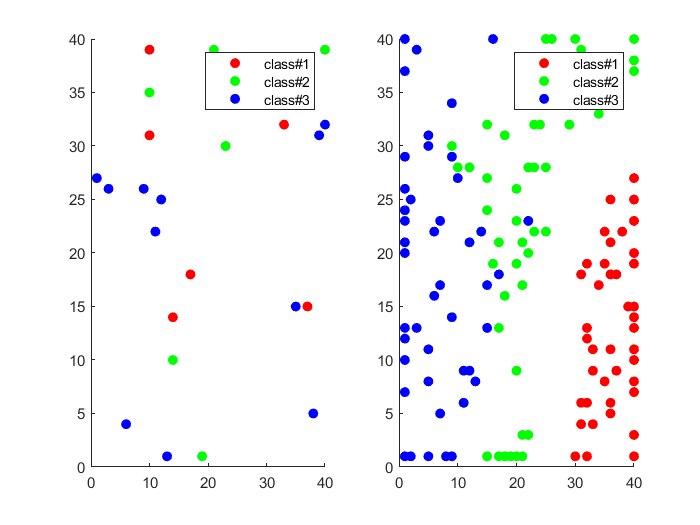

% Plot the classification with randomlized weight
subplot(1,2,1)
hold on
coord = zeros([2,length]);
for idx = 1:length
    X = input_n(idx,:)';
    i0 = find_minimal_distance(W_init, X);
    coord(:,idx) = i0;
end

scatter(coord(1,1:50), coord(2,1:50),[], "r", "filled")
scatter(coord(1,51:100), coord(2,51:100),[], "g", "filled")
scatter(coord(1,100:150), coord(2,100:150),[], "b", "filled")
legend("class#1","class#2","class#3")

% Plot the classification with final weight
subplot(1,2,2)
coord = zeros([2,length]);
for idx = 1:length
    X = input_n(idx,:)';
    i0 = find_minimal_distance(W, X);
    coord(:,idx) = i0;
end
scatter(coord(1,1:50), coord(2,1:50),[], "r", "filled")
hold on
scatter(coord(1,51:100), coord(2,51:100),[], "g", "filled")
scatter(coord(1,100:150), coord(2,100:150),[], "b", "filled")
legend("class#1","class#2","class#3")

function i0 = find_minimal_distance(W, X)
    i0 = zeros([2,1]);
    minimal_d = 100;
    for i =1:40
        for j = 1:40
            current_weight = squeeze(W(i,j,:));
            temp_d = sqrt(dot(current_weight-X, current_weight-X));
            if temp_d < minimal_d
                i0 = [i;j];
                minimal_d = temp_d;
                d = X-current_weight;
            end
        end
    end
end

function h = neightbour_hood(v,sigma)
    h = exp((-1/(2*sigma^2)) *  norm(v)^2);
end

% function w = weight_update()